# Systematic review of SysID - Different models and prediction error methods

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Jingxiao Liu
% Inferlab, CEE, CMU
% June, 2019
% Matlab live script for introducing different dynamic models and 
% prediction error methods for identifying them
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Part 3. Prediction error methods

a) Compute $\hat{y} \left\lbrack k;\theta |k-1\right\rbrack$;

b) Form the prediction error $\epsilon \left\lbrack k\right\rbrack =y\left\lbrack k\right\rbrack -\hat{y} \left\lbrack k;\theta |k-1\right\rbrack$;

c) Construct the loss function $L_N =\frac{1}{N}\sum_{k=1}^N \epsilon^2 \left\lbrack k\right\rbrack$;

d) $\theta^* =\mathrm{arg}\underset{\theta }{\mathrm{min}} {\;L}_N$.

## 3.1 Different model types

## 3.1.1 Finite impulse response (FIR) model


$$y\left(t\right)=b_1 u\left(t-1\right)+b_2 u\left(t-2\right)+\cdots +b_{n_b } \left(t-n_b \right)+e\left(t\right)=\left(\sum_{k=1}^{n_b } b_k q^{-k} \right)u\left(t\right)+e\left(t\right)=B\left(q\right)u\left(t\right)+e\left(t\right)$$


if $n_b$ is infinity, this is a infinite impulse response model

## 3.1.2 Autoregressive exogenous (ARX) model


$$\begin{array}{l}
y\left(t\right)+a_1 y\left(t-1\right)+\cdots +a_{n_a } y\left(t-n_a \right)=b_1 u\left(t-1\right)+b_2 u\left(t-2\right)+\cdots {+b}_{n_b } \left(t-n_b \right)+e\left(t\right)\\
\left(\sum_{k=0}^{n_a } a_k q^{-k} \right)y\left(t\right)=\left(\sum_{k=1}^{n_b } b_k q^{-k} \right)u\left(t\right)+e\left(t\right)\\
y\left(t\right)=\frac{B\left(q\right)}{A\left(q\right)}u\left(t\right)+\frac{1}{A\left(q\right)}e\left(t\right)
\end{array}$$


## 3.1.3 Autoregressive moving average exogenous (ARMAX) model (equation error model family)


$$\begin{array}{l}
y\left(t\right)+a_1 y\left(t-1\right)+\cdots +a_{n_a } y\left(t-n_a \right)=b_1 u\left(t-1\right)+b_2 u\left(t-2\right)+\cdots +b_{n_b } \left(t-n_b \right)+e\left(t\right)+c_1 e\left(t-1\right)+\cdots +c_{n_c } e\left(t-n_c \right)\\
\left(\sum_{k=0}^{n_a } a_k q^{-k} \right)y\left(t\right)=\left(\sum_{k=1}^{n_b } b_k q^{-k} \right)u\left(t\right)+\left(\sum_{k=0}^{n_c } c_k q^{-k} \right)e\left(t\right)\\
y\left(t\right)=\frac{B\left(q\right)}{A\left(q\right)}u\left(t\right)+\frac{C\left(q\right)}{A\left(q\right)}e\left(t\right)
\end{array}$$


## 3.1.4 Output-error model

If the linear difference equation is error-free, but that the noise consists of white measurement noise only:


$$\begin{array}{l}
x\left(t\right)+f_1 x\left(t-1\right)+\cdots +f_{n_f } x\left(t-n_a \right)=b_1 u\left(t-1\right)+b_2 u\left(t-2\right)+\cdots +b_{n_b } \left(t-n_b \right)\\
y\left(t\right)=x\left(t\right)+e\left(t\right)\\
y\left(t\right)=\frac{\left(\sum_{k=1}^{n_b } b_k q^{-k} \right)}{\left(\sum_{k=0}^{n_f } f_k q^{-k} \right)}u\left(t\right)+e\left(t\right)\\
y\left(t\right)=\frac{B\left(q\right)}{F\left(q\right)}u\left(t\right)+e\left(t\right)
\end{array}$$


## 3.1.5 Box-Jenkins model (contains above all)


$$y\left(t\right)=\frac{B\left(q\right)}{F\left(q\right)}u\left(t\right)+\frac{C\left(q\right)}{A\left(q\right)}e\left(t\right)$$


## 3.2 2-DoF mass-spring-damper system

Define stiffness and mass matrices

|\/\/\/\/\O\/\/\/\/\O

   k1 c1  m1  k2 c2  m2


$$M\ddot{X} +C\dot{X} +\textrm{KX}=F$$


clc;
clear;
close all;
addpath ../functions/
m1=5; %mass 1 [kg]
m2=2; %mass 2 [kg]
k1=200; %spring 1 [N/m]
k2=100; %spring 2 [N/m]
c1=10; % damping coeff 1
c2=10; % damping coeff 2
M=[m1 0;0 m2]; %mass matrix
K=[k1+k2 -k2; -k2 k2]; %stiffness matrix
Damp=[c1+c2 -c2; -c2 c2]; % damping matrix
T = 10; %length of time duration
nt = 500; %number of time stamps
Fs = nt/T;
tspan=linspace(0,T,nt);
F = csvread(['../data/ambient.csv']); %load data

## 3.2.1 Load the data generated in script 1

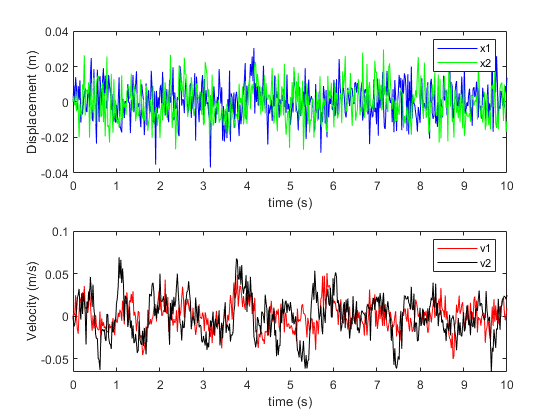

ysol = csvread(['../data/2dof_noP.csv']); %load data
tspan=linspace(0,T,nt);
figure(1)
plot_dv(tspan,ysol')

## 3.2.2 FIR model identification


$${\left\lbrack y\left(n_b \right),\cdots ,y\left(N\right)\right\rbrack }^T =\left\lbrack \begin{array}{cccc}
u\left(n_b -1\right) & u\left(n_b -2\right) & \cdots  & u\left(0\right)\\
u\left(n_b \right) & u\left(n_b -1\right) & \cdots  & u\left(1\right)\\
\vdots  & \vdots  & \; & \vdots \\
u\left(N_1 \right) & u\left(N-2\right) & \cdots  & u\left(N-n_b \right)
\end{array}\right\rbrack \left\lbrack b_1 ,b_2 ,\cdots ,b_{n_b } \right\rbrack T$$


## 3.2.3 ARX model identification


$${\left\lbrack y\left(\mathrm{max}\left(n_a ,n_b \right)\right),\cdots ,y\left(N\right)\right\rbrack }^T =\left\lbrack \begin{array}{cccccc}
-y\left(n_a -1\right) & \cdots  & -y\left(0\right) & u\left(n_a -1\right) & \cdots  & u\left(n_a -n_b \right)\\
-y\left(n_a \right) & \cdots  & -y\left(1\right) & u\left(n_a \right) & \cdots  & u\left(n_a -n_b +1\right)\\
\vdots  & \; & \vdots  & \vdots  & \; & \vdots \\
-y\left(N-1\right) & \cdots  & -y\left(N-n_a \right) & u\left(N-1\right) & \cdots  & u\left(N-n_b \right)
\end{array}\right\rbrack \left\lbrack a_1 ,a_2 ,\cdots ,a_{n_a } ,b_1 ,b_2 ,\cdots ,b_{n_b } \right\rbrack T$$


## 3.2.4 ARMAX model identification


$${\left\lbrack y\left(\max \left(n_a ,n_b ,n_c \right)\right),\cdots ,y\left(N\right)\right\rbrack }^T =\left\lbrack \begin{array}{ccccccccc}
-y\left(n_a -1\right) & \cdots  & -y\left(0\right) & u\left(n_a -1\right) & \cdots  & u\left(n_a -n_b \right) & \epsilon \left(n_a -1\right) & \cdots  & \epsilon \left(n_a -n_c \right)\\
-y\left(n_a \right) & \cdots  & -y\left(1\right) & u\left(n_a \right) & \cdots  & u\left(n_a -n_b +1\right) & \epsilon \left(n_a \right) & \cdots  & \epsilon \left(n_a -n_c +1\right)\\
\vdots  & \; & \vdots  & \vdots  & \; & \vdots  & \vdots  & \; & \vdots \\
-y\left(N-1\right) & \cdots  & -y\left(N-n_a \right) & u\left(N-1\right) & \cdots  & u\left(N-n_b \right) & \epsilon \left(N-1\right) & \cdots  & \epsilon \left(N-n_c \right)
\end{array}\right\rbrack \left\lbrack a_1 ,a_2 ,\cdots ,a_{n_a } ,b_1 ,b_2 ,\cdots ,b_{n_b } ,c_1 ,{\cdots ,c}_2 \right\rbrack T$$


Need iterative solution

## 3.2.5 Output error identification

Similar to ARMAX, but error does not shift.

## 3.3 Prediction error method

All above can be generalizaed by considering the equation and out errors as prediction errors.

## 3.3.1 Deterministic model with one step information


$$\begin{array}{l}
x\left\lbrack k+1\right\rbrack =A\;x\left\lbrack k\right\rbrack +B\;u\left\lbrack k\right\rbrack \\
y\left\lbrack k+1\right\rbrack =C\;x\left\lbrack k+1\right\rbrack \\
y\left\lbrack k+1\left|k\right.\right\rbrack =C\;A\;C^{-1} y\left\lbrack k\right\rbrack +C\;B\;u\left\lbrack k\right\rbrack \\
\theta^* =\arg \min_{\theta } \;\frac{1}{N}\sum_{k=0}^{N-1} {\left(y\left\lbrack k+1\right\rbrack -\hat{y} \left\lbrack k+1|k\right\rbrack \right)}^2 
\end{array}$$


rng(49)
params_ini = [1,1,100,100,5,5];
options = optimset('TolFun',10e-15);
params = zeros(6,6);
filenames = {'../data/2dof.csv','../data/2dof_noP.csv','../data/2dof_P6.csv','../data/2dof_P5.csv','../data/2dof_P4.csv','../data/2dof_P3.csv'};
for i=1:6
    ysol = csvread(filenames{i});
    pe = @(pa)pe_func(pa,tspan,F,ysol);
    params(i,:) = fmincon(pe,params_ini,[],[],[],[],[0,0,0,0,0,0],...
                            [10,10,300,300,20,20],[],options);
end


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the default value of the step size tolerance and constraints are 
satisfied to within the default value of the constraint tolerance.

<stopping criteria details>




True parameters:

disp([m1,m2,k1,k2,c1,c2])

     5     2   200   100    10    10



Estimated parameters

disp(params)

    4.9997    2.0000  199.9864   99.9995   10.0017   10.0001
    2.9936    2.0927    6.1589    0.0001   19.9999   19.9993
    5.8706    2.3510    0.0000    0.0000    6.2452   19.0026
    5.7234    1.9322    0.0013   17.8977   19.9992    2.7900
    6.9048    2.4573  188.7143   96.9373   19.4295    8.9579
    3.1003    1.7399  123.2224   77.2227    6.5086    7.8601



## 3.3.2 Deterministic model without previous information


$$\begin{array}{l}
x\left\lbrack k+1\right\rbrack =A\;x\left\lbrack k\right\rbrack +B\;u\left\lbrack k\right\rbrack \\
y\left\lbrack k+1\right\rbrack =C\;x\left\lbrack k+1\right\rbrack \\
\hat{y} \left\lbrack k+1\right\rbrack =C\;A^k \;x\left\lbrack 0\right\rbrack +C\;B\;u\left\lbrack k\right\rbrack \\
\theta^* =\mathrm{arg}\underset{\theta }{\mathrm{min}} \;\frac{1}{N}\sum_{k=1}^N {\left(y\left\lbrack k\right\rbrack -\hat{y} \left\lbrack k\right\rbrack \right)}^2 
\end{array}$$


x0=[0;0;0;0]; %initialization of states
C = [1,0,0,0;
     0,1,0,0;
     0,0,1,0;
     0,0,0,1]; %observation matrix
params1 = zeros(6,6);
for i=1:6
    ysol = csvread(filenames{i});
    pe = @(pa)pe1_func(pa,tspan,x0,C,F,ysol);
    params1(i,:) = fmincon(pe,params_ini,[],[],[],[],[0,0,0,0,0,0],...
                            [10,10,300,300,20,20],[],options);
end


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the default value of the step size tolerance and constraints are 
satisfied to within the default value of the constraint tolerance.

<stopping criteria details>




disp(params1)

    5.0000    2.0000  199.9994  100.0005   10.0003    9.9999
    5.5827    1.9749  219.3015   98.8743    9.5965    8.5350
    3.3593    2.0498  188.5633   78.1357    5.6857    7.0251
    0.6686    2.2558   96.5856  299.9998    0.0000   11.8992
    1.4199    0.7358   95.1074    0.0016    0.0001   19.9982
    0.4877    0.3804   38.4027    0.0073    0.0001   19.9746

